# Multi notes detection on spectrum

The main idea is to eject from spectrum all samples that relays to each note, make individual vectors of spectrum samples for each note. After that each classifier will be learned to detect one single note. Because specific classifier gets only samples related to single note - the result of classification will not be changed by adding other notes to compusition in that specific time frame.

#### Load the data

z - digital sound signal for learning/testing model

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

clear y path path1

#### Define constants

OCTAVES = 7;              % Number of octaves for classification
NPO = 12;                 % Number of notes per octave
NOTES = OCTAVES*NPO;      % Number of notes for classification
CLASSES = NOTES + 1;      % Adds a 'pause' class
NFFT = 1024;              % Window width for Fourier transform
df = 1;                   % Desired frequency step in spectrum 
N_zero = floor(df*(Fs - NFFT));  % Number of zeros needed for interpolation
t_n = 0.5;                % Time in seconds for each note in signal z (max - 2, normal - 1)
N = floor(t_n/(NFFT/Fs)); % Number of cuts for each note in signal z
ds = 11;                  % Times the spectrum will decrease. Min - 2

clear t_n df

#### Prepare z for using - make matrix data

data = reshape(z,4*Fs,[]);  % Make each note separate
data = data(1:N*NFFT, :);   % Remove all pauses
data = data(:, 1:87);       % Remove C 5th octave
data = data(:,4:end);       % Remove first 3 notes (wrong octave)

% A pause class 
S = 10e-5*rand(N*NFFT,1);
S = S - mean(S);
% S = wgn(1,N*NFFT,1) / 100;
% plot(S)
% plot(abs(fft(S)))

data = [S, data];

clear z S

#### Define frequencies for each note

Tab_F - matrix with size: "number of octaves" x "number of notes in octave". Each cell represents freqency of specific note for specific octave

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:OCTAVES-1) / 2;
Tab_F = k' .* repmat(Tab_F_1, OCTAVES, 1);    
Indexes = floor(Tab_F);

clear k Tab_F_1 Tab_F

#### Create masks for each note

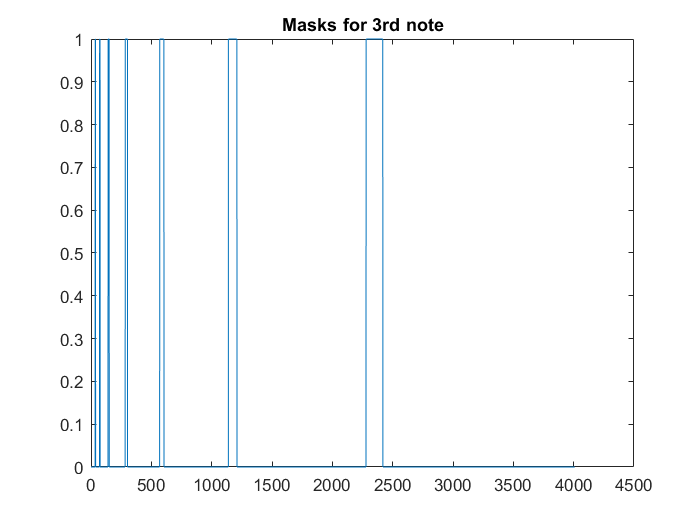

N_spec = floor((NFFT + N_zero) / ds);   % Total count of spectum samples after processing
masks = zeros([NPO, N_spec]);           % Masks for each note

for i = 1:NPO
    j = 1:OCTAVES;     
    
    if i == NPO
        n1 = Indexes(j,i-1);
        n2 = Indexes(j,i);
        
        dif = floor((n2 - n1)/2);   % Let the distance be equal to the left and rigt of note freqency
        for ii = 1:length(n1)
            d1 = min(n2(ii)-dif(ii), N_spec-1);
            d2 = min(n2(ii)+dif(ii), N_spec);
            masks(i, d1:d2) = ones(1, (d2-d1)+1);
        end  
    else
        n1 = Indexes(j,i);
        n2 = Indexes(j,i+1);
        
        dif = floor((n2 - n1)/2);   % Let the distance be equal to the left and rigt of note freqency
        for ii = 1:length(n1)
            masks(i, n1(ii)-dif(ii):n1(ii)+dif(ii)) = ones(1, 2*dif(ii)+1);
        end  
    end
            
end

% Make 0001000 where 1 - represents note frequency
Flat_Index = reshape(Indexes', [1, NOTES]);
f = zeros([1, N_spec]);
for i = 1:N_spec
    n = find(Flat_Index == i);
    
    if n >= 1
        f(i) = 1;
    else
        f(i) = 0;
    end
end

figure
plot(1:N_spec, masks(3,:))
title('Masks for 3rd note')

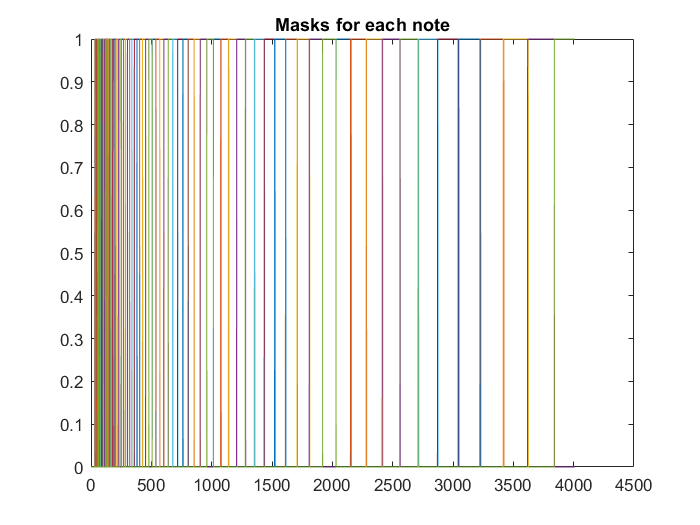


figure
plot(1:N_spec, masks(:,:))
title('Masks for each note')

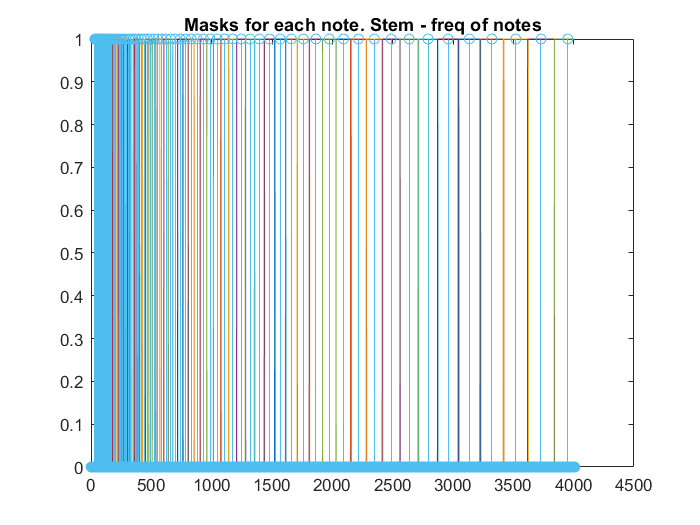


figure
plot(1:N_spec, masks(:,:))
hold on
stem(f)
title('Masks for each note. Stem - freq of notes')


clear n n1 n2 d1 d2 j i ii dif f Flat_Index ds

#### Create data for training/testing classifiers

Y - vector of labels

X - matrix, where each row represents digital sound signal with window function and N_zero zeros in the end for further interpolation

Number of rows are equal for Y and X, what means that signal in X(i,:) has label Y(i)

Y = zeros(N*CLASSES, 1);
X = zeros([N*CLASSES, NFFT+N_zero]);  % With interpolation
% X = zeros([N*NOTES, NFFT]);       % Without interpolation

for k=1:CLASSES
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    notes = reshape(data(:,k),NFFT,[])';
    
    % Add Hamming window
    h = hamming(NFFT)';
    notes = notes .* h;
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
end

clear N1 N2 h notes k data

#### Prepare data for training/testing classifiers

Training data should be first N_spec normalized samples of interpolated spectrum of each X row

X_spec = abs(fft(X'))';                     % Find spectrum of each signal
X_ds(:, 1:N_spec) = X_spec(:, 1:N_spec);    % Left only first N_spec samples
X_energy = sum(X_ds, 2);                    % Energy estimation %    sum(X_ds.*X_ds, 2);
X_energy = X_energy - min(X_energy);
% X_energy = sqrt(X_energy);
X_energy = X_energy ./ max(X_energy);       % Energy normalizing
X_max =  max(X_ds, [], 2);                  % Max val in spectrum
X_max = X_max - min(X_max);
% X_max = sqrt(X_max);
X_max =  X_max ./ max(X_max);               % Max val normalization
X_ds = X_ds - min(X_ds, [], 2);
X_ds = X_ds ./ max(X_ds, [], 2);            % Data normalization by max
% X_ds = X_ds ./ sum(X_ds, 2);              % Data normalization by sum

% Should be removed!!!
X_ds = X_ds + 0.0001;                       % Makes all samples non zero (to not delete these samples)

clear X X_spec

#### Separate data

cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X_ds(trainInds,:);
XTrain_energy = X_energy(trainInds);
XTrain_max = X_max(trainInds);
YTrain = Y(trainInds);
XTest = X_ds(testInds,:);
XTest_energy = X_energy(testInds);
XTest_max = X_max(testInds);
YTest = Y(testInds);

save('Train_Test_data.mat', 'XTrain', 'YTrain', 'XTest', 'YTest', 'XTrain_energy', 'XTest_energy')

clear X_ds Y cv trainInds testInds

#### Train an array of SVM models

Mdl_Cell - is a cell array, cell number "j" contains a binary classification SVM model which says that signal is note "j" or not.

[row_num, ~] = size(XTrain);

tic
for i = 1:CLASSES
    
    % Noise|Pause (i=0) doesn't use masks
    if i == 1
        
        XTrain_cell = XTrain;
        
    else
        % Choose mask m for classifier
        ind_mask = mod(i - 1,12) + 1;   % +1 - shift after pause, -1 - to shift from 0-11 to 1-12
        m = masks(ind_mask, :);
        
        % Multiply spectrum with mask and remove zeros
        % 5057x4009 --> 5057x(253-386) depending on mask
        XTrain_cell = XTrain .* m;
        XTrain_cell(XTrain_cell==0)=[];
        XTrain_cell = reshape(XTrain_cell, row_num, []);
    end
    
    XTrain_cell = [XTrain_energy XTrain_cell];   % Add energy to features vector
    XTrain_cell = [XTrain_max XTrain_cell];      % Add max spectrum val 
    
    YTrain_cell = i*(YTrain==i);
    
    Mdl_Cell{i} = fitcecoc(XTrain_cell,YTrain_cell);    
    
end
toc

Elapsed time is 4.731534 seconds.



% save('Mdl_Cell_Array', 'Mdl_Cell')        % 1.17 Gb

clear i m x ind_mask XTrain_cell YTrain_cell row_num
clear XTrain YTrain

#### Test an array of SVM models

[row_num, ~] = size(XTest);

tic
for i = 1:CLASSES
    
    % Noise|Pause (i=0) doesn't use masks
    if i == 1
        
        XTest_cell = XTest;
        
    else
        % Choose mask m for classifier
        ind_mask = mod(i-1,12) + 1;   % +1 - shift after pause, +1 - to shift from 0-11 to 1-12
        m = masks(ind_mask, :);
        
        % Multiply spectrum with mask and remove zeros
        % 5057x4009 --> 5057x(253-386) depending on mask
        XTest_cell = XTest .* m;
        XTest_cell(XTest_cell==0)=[];
        XTest_cell = reshape(XTest_cell, row_num, []);
    end
    
    XTest_cell = [XTest_energy XTest_cell];   % Add energy to features vector
    XTest_cell = [XTest_max XTest_cell];     % Add max spectrum val 
    
    
    Labels(i, :) =  predict(Mdl_Cell{i}, XTest_cell);
    
end
toc

Elapsed time is 1.200643 seconds.


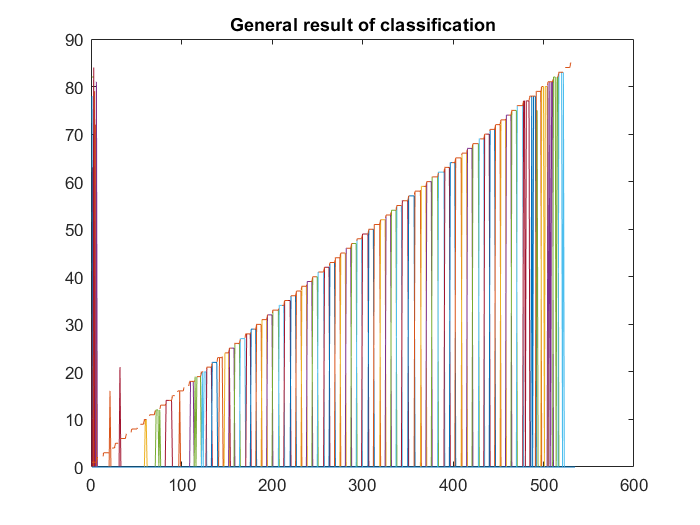


figure
plot(Labels')
hold on
plot(YTest, '--')
title('General result of classification')

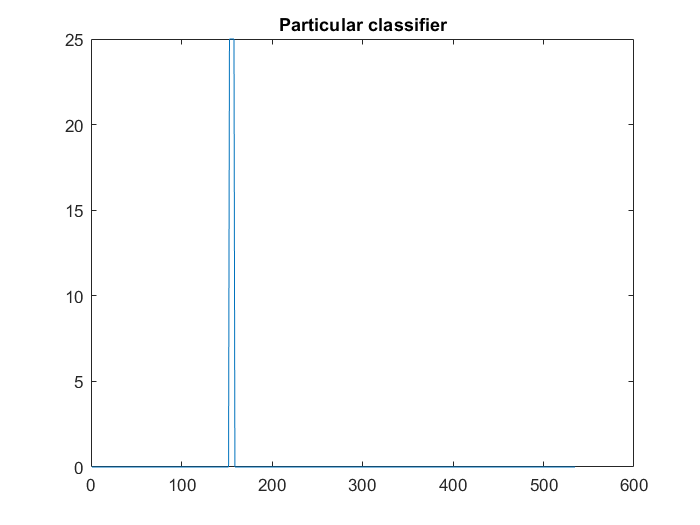


figure
plot(Labels(25,:))
title('Particular classifier')


clear i ind_mask m XTest_cell row_num
clear XTest YTest

#### Test with mario solo

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Examples\My_mario.wav";
[seq, Fs] = audioread(path);

% Make size of seq dividable by NFFT
div = floor(length(seq) / NFFT);
seq = seq(1:div*NFFT);

% Matrix for sequence to get interpolated spectrum
s = zeros([div, NFFT+N_zero]);

% Fill matrix s with seq and window function
for i = 1:div
    n1 = (i-1)*NFFT + 1;
    n2 = i*NFFT;
    
    h = hamming(NFFT);
    seqh = seq(n1:n2) .* h;
    
    s(i, 1:NFFT) = seqh;
end

clear path seq n1 n2 i h seqh

% Find spectrum
s_spec = abs(fft(s'))';

% Left only first N_spec samples
s_ds(:, 1:N_spec) = s_spec(:, 1:N_spec);

S_energy = sum(s_ds, 2);    
S_energy = S_energy - min(S_energy);        % Energy estimation %    sum(X_ds.*X_ds, 2);
% S_energy = sqrt(S_energy);
S_energy = S_energy ./ max(S_energy);       % Energy normalizing

S_max =  max(s_ds, [], 2);                  % Max val in spectrum
S_max = S_max - min(S_max);
% S_max = sqrt(S_max);
S_max =  S_max ./ max(S_max);               % Max val normalization


% Normalization by max
s_ds = s_ds ./ max(s_ds, [], 2); 

% Should be removed!!!
s_ds = s_ds + 0.0001;                       % Makes all samples non zero (to not delete those samples)

clear s seq s_spec

[row_num, ~] = size(s_ds);

tic
for i = 1:CLASSES
    
    % Noise|Pause (i=0) doesn't use masks
    if i == 1
        
        s_ds_cell = s_ds;
        
    else
        % Choose mask m for classifier
        ind_mask = mod(i-1,12) + 1;   % +1 - shift after pause, +1 - to shift from 0-11 to 1-12
        m = masks(ind_mask, :);
        
        % Multiply spectrum with mask and remove zeros
        s_ds_cell = s_ds .* m;
        s_ds_cell(s_ds_cell==0)=[];
        s_ds_cell = reshape(s_ds_cell, row_num, []);
    end
    
    s_ds_cell = [S_energy s_ds_cell];
    s_ds_cell = [S_max s_ds_cell];

    Labels_mario(i, :) =  predict(Mdl_Cell{i}, s_ds_cell);
    
end
toc

Elapsed time is 0.967360 seconds.


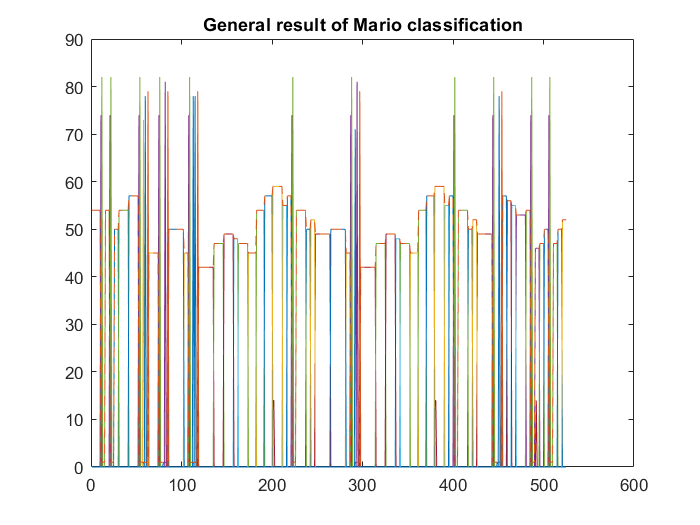


clear row_num i ind_mask m s_ds_cell s_ds div 

load('D:\Desktop\Studie\Diploma\GIT Matlab\Examples\Yreal_notes.mat')

figure
plot(Labels_mario')
hold on 
plot(Yreal_notes, '--')
title('General result of Mario classification')